In this exercise we will learn how to extract spikes and local field potentials from extracellular recordings. The data we will use comes from Michale Fee’s lab, and are extracellular recording from the lateral magnocellular nucleus of the anterior neostriatum (LMAN) of a zebra finch. LMAN generates exploratory variations during singing, and is necessary for learning song acoustics. 

The raw data, saved in *dataFee.mat*, was sampled at 30 kHz and has units of microvolts (μV) 

First, we will extract the local field potential, the lower-frequency part of the signal that reflects the combined synaptic input to many neurons. To do this, we will construct a low-pass filter. Then we will filter using convolution (‘`conv`’). 

Next, we will extract the spikes using a high-pass filter, note that spikes are brief events of high frequency content (above 500Hz). 

## Load data and Parameters

load dataFee.mat
Fs = 30000;
dt = 1/Fs;
N = numel(rawData);

## Plot first second of data

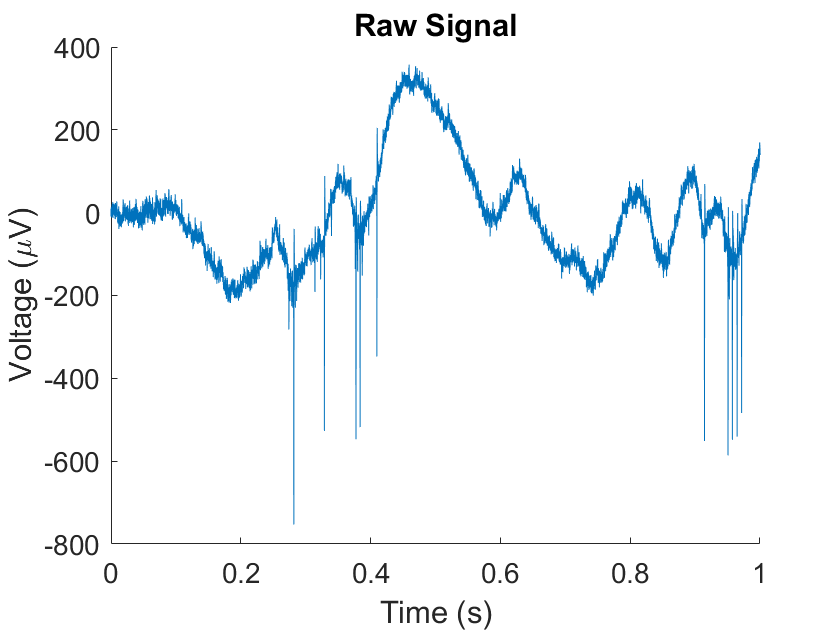

t = (0:N-1)*dt;
plot(t, rawData);
xlim([0 1]);
xlabel('Time (s)', 'FontSize',16);
ylabel('Voltage (\muV)', 'FontSize',16);
title('Raw Signal', 'FontSize',16)
box off;
ax = gca;
ax.FontSize = 14;

## Make Low pass filter

Box car of width 10 msec

FilterWidth = 0.01; % Seconds
FilterSamples = round(Fs*FilterWidth);
% Ensure Filter has an odd number of elements so kernel is perfectly centered for convolution
if mod(FilterSamples,2)==0
    FilterSamples = FilterSamples + 1;
end
LPfilter = ones (1,FilterSamples)/FilterSamples; % Make area = 1;

## Filter Signal:

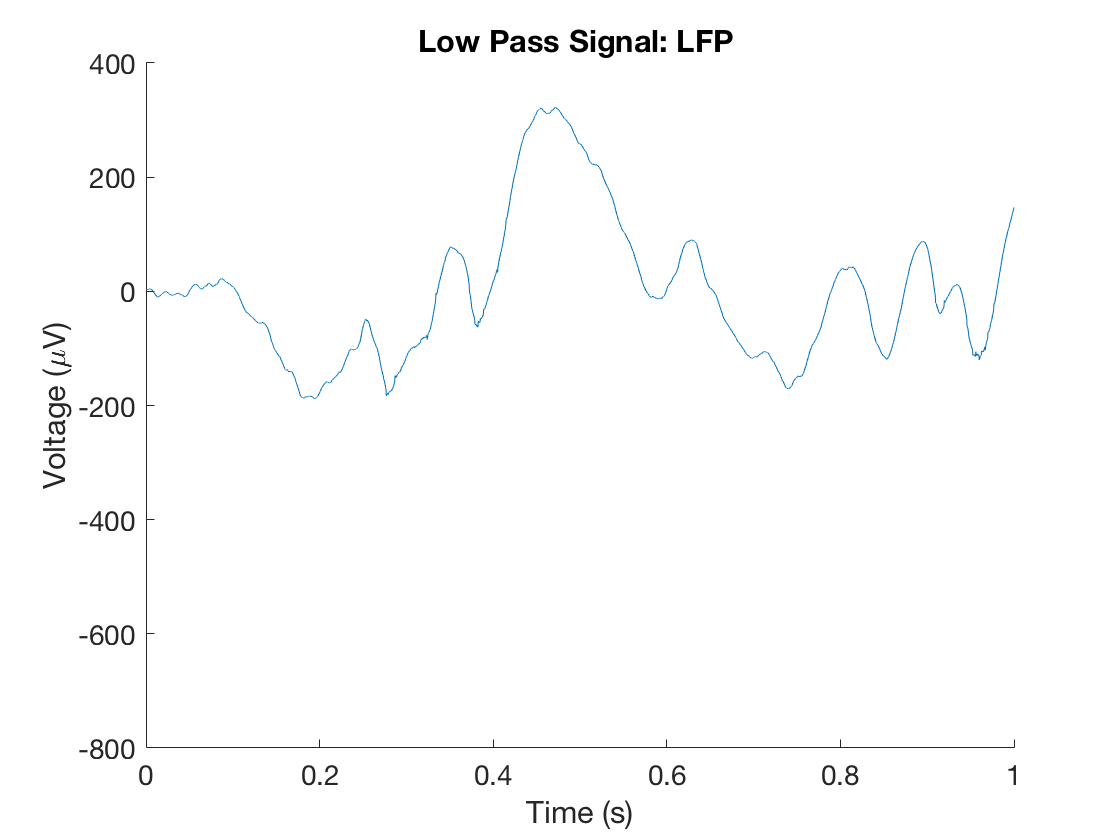

LowPassData = conv(rawData,LPfilter,'same');
plot(t, LowPassData);
xlim([0 1]);
ylim([-800 400])
xlabel('Time (s)', 'FontSize',16);
ylabel('Voltage (\muV)', 'FontSize',16);
title('Low Pass Signal: LFP ', 'FontSize',16)
box off;
ax = gca;
ax.FontSize = 14;

## HighPass Filter

HPFilter = -LPfilter;
HPFilter(ceil(FilterSamples/2))= (FilterSamples-1)/FilterSamples; % Make total area = 0

## Filter the signal

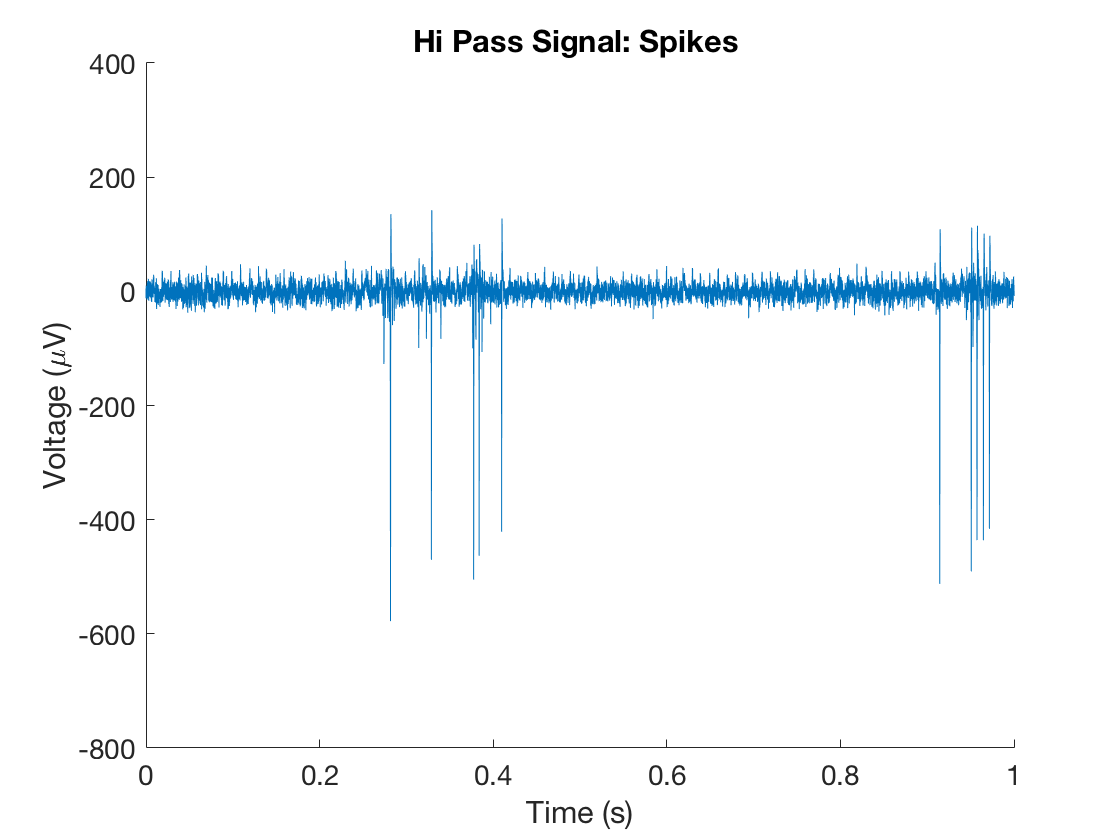

HiPassData = conv(rawData,HPFilter,'same');
plot(t, HiPassData);
xlim([0 1]);
ylim([-800 400])
xlabel('Time (s)', 'FontSize',16);
ylabel('Voltage (\muV)', 'FontSize',16);
title('Hi Pass Signal: Spikes ', 'FontSize',16)
box off;
ax = gca;
ax.FontSize = 14;

## Another way to do a HP filtering.

Subtract low pass fromraw signal 

HiPassData_2 = rawData - LowPassData;
plot(t, HiPassData_2);
xlim([0 1]);
ylim([-800 400])
xlabel('Time (s)', 'FontSize',16);
ylabel('Voltage (\muV)', 'FontSize',16);
title('Hi Pass Signal: Spikes ', 'FontSize',16)
box off;
ax = gca;
ax.FontSize = 14;